# `矩阵的拼接和重复`

## `矩阵的拼接`

`有时候我们需要对多个矩阵进行拼接，变成一个大的矩阵。`

`根据矩阵拼接的方向，我们可以分为横向`(`水平`)`拼接和纵向`(`垂直`)`拼接，如下图所示：`

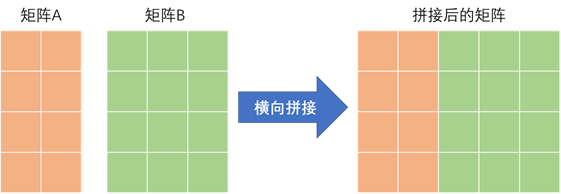

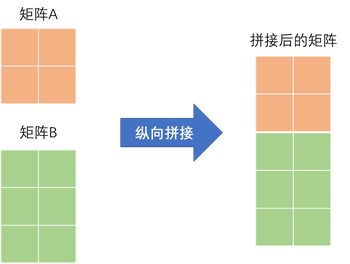

`如上图所示：横向拼接要求矩阵的行数相同；纵向拼接要求矩阵的列数相同。`

`在`MATLAB`中，我们可以使用命令`[A, B] `或` [A  B]`对矩阵`A`和`B`进行横向拼接，也可以使用`MATLAB`中的内置函数：`horzcat(A,B)`；`

A = [1 6 7; 4 5 7]
B = [3 1; 5 10]
[A, B]

[A B] % 用空格隔开，可以有多个空格
horzcat(A,B)
cat(2,A,B)

`类似的，我们可以使用命令`[A; B]`对矩阵`A`和`B`进行纵向拼接，也可以使用`MATLAB`中的内置函数：`vertcat(A,B)`。`

A = [2 4 5;2 2 4]
B = [1 8 6;6 3 10;1 5 5]
[A; B]
[A
 B]  % 也可以使用回车键进行纵向拼接
vertcat(A,B)
cat(1,A,B)

事实上，horzcat和vertcat两个函数来源自cat函数，这里的cat不是猫的意思，而是单词catenate的缩写，下面是cat函数的帮助链接：

[https://ww2.mathworks.cn/help/matlab/ref/double.cat.html](https://ww2.mathworks.cn/help/matlab/ref/double.cat.html)

命令cat(dim,A,B)表示沿维度 dim 方向将矩阵B拼接到矩阵A的末尾。

dim = 1时表示从上自下沿着行方向拼接，即纵向拼接，因此cat(1,A,B)等价于vertcat(A,B)；

dim = 2时表示从左自右沿着列方向拼接，即横向拼接，因此cat(2,A,B)等价于horzcat(A,B)。

大小不匹配会报错

A = ones(2)
B = ones(3)
% [A,B]
% [A;B]

多个矩阵的拼接

A = ones(2)
B = zeros(2)
C = eye(2)
[A B C]
cat(2,A,B,C)
horzcat(A,B,C)
[A;B;C]
[A
 B
 C]
cat(1,A,B,C)
vertcat(A,B,C)


## `矩阵的重复`

`有时候我们需要对同一个矩阵进行重复的堆叠。`

`例如将矩阵`A`的内容堆叠在m行n列的新矩阵中，这个新矩阵每一行由`n`个`A`组成，每一列由m个`A`组成。`

`下面我们画一个示意图：`

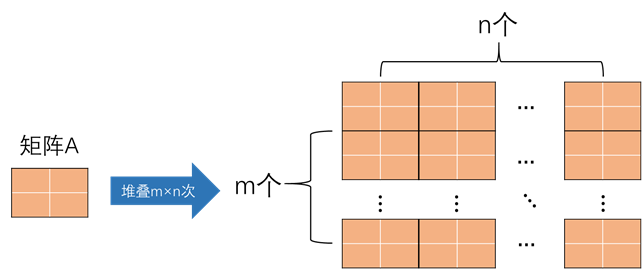

`在`MATLAB`中，对同一个矩阵进行重复的堆叠的代码为`**repmat(A,m,n)**`。`

A = 1:4
B = repmat(A,3,1)
B = repmat(A,3,2)
C = [1,2;
     3,4]
D = repmat(C,2,3)

## 对向量或者矩阵中的元素进行重复

`除了对整个矩阵进行重复的堆叠外，`**MATLAB**`还可以对向量或者矩阵中的元素进行重复，使用到的函数是`**repelem**`。`

`（这个函数使用的较少，大家了解即可）`

`情况1：重复向量`**v**`中的元素：`**repelem(v,n)**

- `当`n`为一个正整数时，表示把向量`v`中的每一个元素都重复`n`次；`

- n`也可以为一个向量，其长度必须和`v`的长度相同，它可以将`v`的每个元素指定重复`n`对应元素的次数。`

v = [5,3,8];
repelem(v,2)
repelem(v,[2,1,4])

`情况2：重复矩阵`**A**`中的元素：`**repelem(A,m,n)**

m`和`n`分别表示沿着行方向`(`从上至下`)`和列方向`(`从左至右`)`将矩阵元素重复的次数，这里的`m`和`n`可以是正整数，也可以是向量。`

`如果`m`是向量，则`m`的长度要和矩阵`A`的行数相同；如果`n`是向量，则`n`的长度要和矩阵`A`的列数相同。`

A = [2,3,5;
     8,4,7];
repelem(A,3,2) % 沿着行方向重复3次，沿着列方向重复2次
% 沿着行方向：第一行重复2次，第二行重复3次
% 沿着列方向：第一列重复1次，第二列重复2次，第三列重复3次
repelem(A,[2,3],[1,2,3])

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)